Open it as live script!!!

Load the indian_pines dataset and use it to initialize a HSI object.

clear;
load('Data\Indian_pines.mat');
h = HSI(indian_pines);
clear indian_pines;
disp(h);

  HSI with properties:

      him: [145×145×220 double]
    shape: [145 145 220]



The default method of .preprocess() is 'normalize'.

h.preprocess();
m1 = max(h.him(:, :, 1), [], 'all');
m2 = min(h.him(:, :, 1), [], 'all');
disp(['The max value of the fisrt band is ', num2str(m1), '.']);

The max value of the fisrt band is 1.


disp(['The min value of the fisrt band is ', num2str(m2), '.']);

The min value of the fisrt band is 0.



h.preprocess('std');
sigma = std(h.him(:, :, 1), [], 'all');
mu = mean(h.him(:, :, 1), 'all');
disp(['The standard deviation of the fisrt band is ', num2str(sigma), '.']);

The standard deviation of the fisrt band is 1.


disp(['The mean value of the fisrt band is ', num2str(mu), '.']);

The mean value of the fisrt band is 6.7531e-14.


You can use .rgb() to view the three-band composite image.

The degree parameter indicates the power of noise.

degree = 1 means there is no noise in the data.

The default value of degree is 0.5;

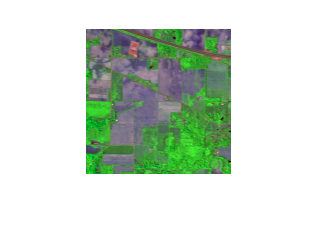

degree = 0.3;
rgb1 = h.rgb(degree);
rgb2 = h.rgb(1);
imshow(rgb1);

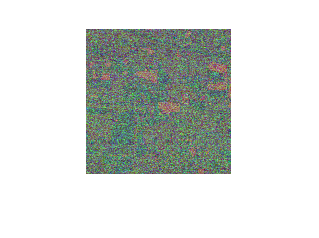

imshow(rgb2);

You can use .F() to obtain the 2D array of the data.

X = h.F();
disp(['The size of X is [', num2str(size(X)), '].']);

The size of X is [21025    220].


You can use .select_bands to obtain the bands you want.

D1 = h.select_bands([1, 2]);
D2 = h.select_bands([1, 2], '1D');
disp(['The size of D1 is [', num2str(size(D1)), '].']);

The size of D1 is [145  145    2].


disp(['The size of D2 is [', num2str(size(D2)), '].']);

The size of D2 is [21025      2].


You can use .remove_bands to remove the noisy bands.

fprintf('The number of the bands is %d.', h.shape(end));

The number of the bands is 220.

rm_list = 1:10;
h.remove_bands(rm_list);
fprintf('The number of the bands is %d.', h.shape(end));

The number of the bands is 210.

You can use .locate to obtain the pixel you interested.

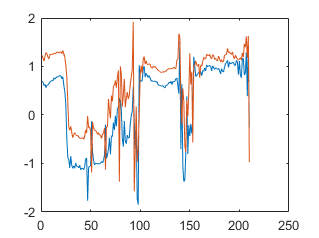

loc_1D = [1, 146];
loc_2D = [1, 1; 2, 1];
plot(h.locate(loc_2D)');

plot(h.locate(loc_1D, '1D')');